# Zr-1Nb-1Sn Processing Map

data = readtable('Alpha-Zr.xlsx');
data.Properties.VariableNames = {'Strain','Strain Rate','T1','T2','T3','T4','T5'}

data = 31×7 table
    Strain    Strain Rate     T1       T2       T3       T4       T5  
    ______    ___________    _____    _____    _____    _____    _____

     NaN           NaN         650      700      750      800      850
     0.1         0.001        66.1     58.8     32.6       30     23.8
     0.1          0.01        97.3     82.1     56.8     43.4     38.4
     0.1           0.1       157.7    125.1     78.3     62.7     50.2
     0.1             1       149.3    145.5    155.6    132.3     95.4
     0.1            10       175.2    168.6    160.9      160    145.1
     0.1           100       210.8    185.9      146    165.4    159.9
     0.2         0.001        68.5     56.7     31.1     27.4     22.4
     0.2          0.01       101.

data(1,:)=[];

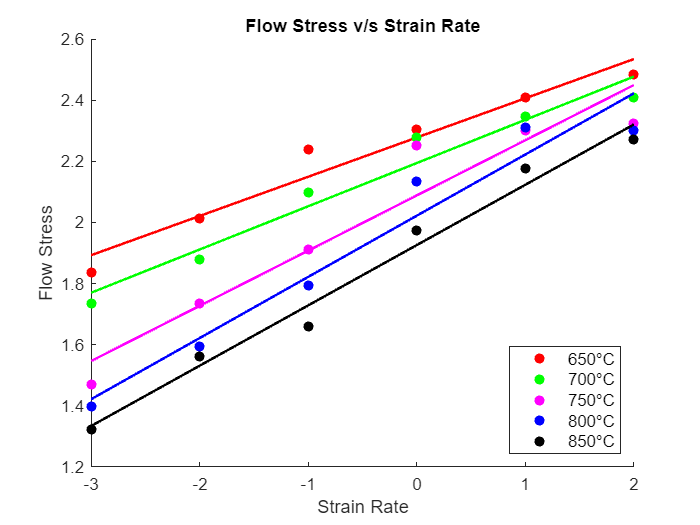

datan= table2array(data);
% 0.3 strain
strain_1 = datan(13:18,2:end);
sr1 = strain_1(:,1);
strainlog = log10(sr1);
stress1 = strain_1(:,2:end);
y = zeros(6,5);
stresslog = log10(stress1);
C = {'r','g','m','b','k'};
hold on
for r = 1:5
    Scatter(r) =scatter(strainlog,stresslog(:,r),'filled','MarkerFaceColor',C{r});
    c= polyfit(log10(sr1),log10(stress1(:,r)),1);
    y(:,r) = polyval(c,log10(sr1));
    plot(log10(sr1),y(:,r),'LineWidth',1.5,'Color',C{r})
end
ylabel('Flow Stress');xlabel('Strain Rate');
title('Flow Stress v/s Strain Rate')
legend(Scatter,'650°C','700°C','750°C','800°C','850°C','Location','southeast','FontSize',10);
hold off

%slope or strain rate sensitivity
%slope or strain rate sensitivity
m= zeros(6,5);
for k =  1:5
 for p = 1:6 
        c1= polyfit(log10(sr1),log10(stress1(:,k)),3);
        deriv = polyder(c1);
        m(p,k) = polyval(deriv,strainlog(p));
 end
end


e= (2*m./(m+1))*100;
T= 650:50:850;
%instability zone
e1= e/200;
slope= zeros(6,5);
for k =  1:5
    for p =  1:6
        c2= polyfit(log10(sr1),log10(e1(:,k)),3);
        deriv = polyder(c2);
        slope(p,k) = polyval(deriv,strainlog(p));
       
    end
end
iz = slope +m;

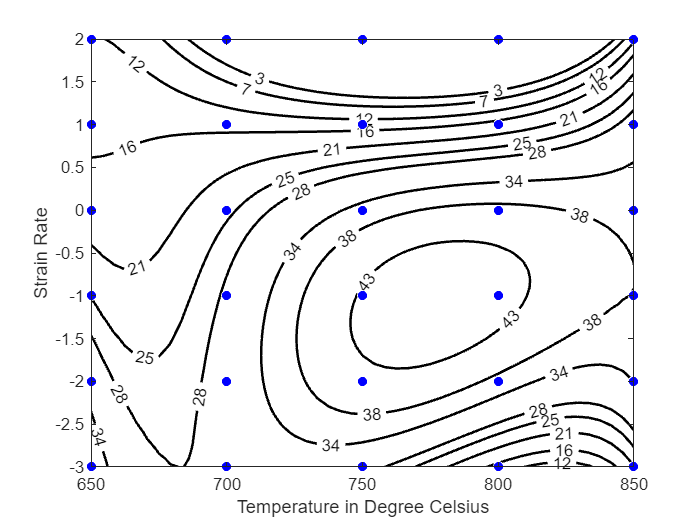

%% Fit: 'untitled fit 1'.
[xData, yData, zData] = prepareSurfaceData( T, strainlog, e );

% Set up fittype and options.
ft = fittype( 'poly45' );

% Fit model to data.
[fitresult] = fit( [xData, yData], zData, ft, 'Normalize', 'on' );

% Make contour plot.
figure( 'Name', 'Power Dissipation' );
h = plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );
% Label axes
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );
ylabel( 'Strain Rate', 'Interpreter', 'none' );

grid off
set(h(1),'ShowText','on','LabelSpacing',144)
set(h(1),'LineWidth',1.5,'Fill','off');
set(h(1),'LevelList',[3,7,12,16,21,25,28,34,38,43])
fig = gcf;
saveas(gcf,'pd.jpg')


%% Fit: 'untitled fit 2'.
[xData, yData, zData] = prepareSurfaceData( T, strainlog, iz );

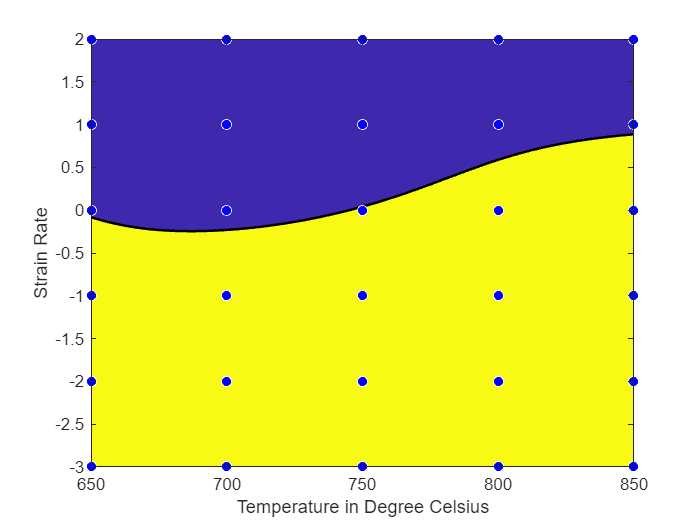


% Set up fittype and options.
ft = fittype( 'poly25' );

% Fit model to data.
[fitresult] = fit( [xData, yData], zData, ft, 'Normalize', 'on' );

% Make contour plot.
figure( 'Name', 'untitled fit 2' );
w=plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );
% Label axes
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );
ylabel( 'Strain Rate', 'Interpreter', 'none' );
grid off
set(w(1),'LineWidth',1.5,'LevelStep',1);
fig = gcf;
saveas(gcf,'is.jpg')

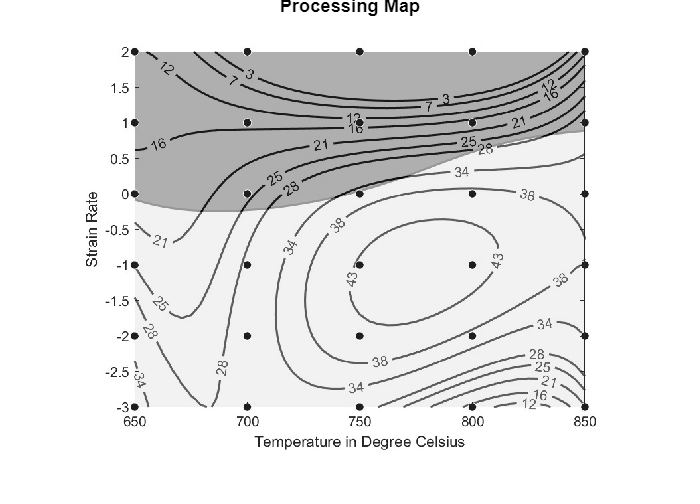

% BASIC IMAGE PROCESSING : SUPERIMPOSE
fig1 = imread('pd.jpg');
fig2 = imread('is.jpg');
fusionimage=imfuse(fig1,fig2,'falsecolor','Scaling','joint');
op=rgb2gray(fusionimage);
imshow(op);
title('Processing Map')